clear all
close all
syms R1 R2 C Ep  s E t
netlist={'V1 1 0 Ep'
    'R1 1 2 R1'
    'R2 2 3 R2'
    'C1 3 0 C'};
[X name]=fspice(netlist)

** fspice 2.43  ** (c) Frederic Martinez


$$X = \left(\begin{array}{c} \mathrm{Ep}\\ \frac{\mathrm{Ep}\,\left(C\,R_{2}\,s+1\right)}{C\,R_{1}\,s+C\,R_{2}\,s+1}\\ \frac{\mathrm{Ep}}{C\,R_{1}\,s+C\,R_{2}\,s+1}\\ -\frac{C\,\mathrm{Ep}\,s}{C\,R_{1}\,s+C\,R_{2}\,s+1} \end{array}\right)$$

name = 1×4 cell array
    {'V(1)'}    {'V(2)'}    {'V(3)'}    {'I(V1)'}


Ep=E/s %TL de e(t)

$$Ep = \frac{\text{E}}{s}$$

S=subs(X(2)) %TL de s(t)

$$S = \frac{\text{E}\,\left(C\,R_{2}\,s+1\right)}{s\,\left(C\,R_{1}\,s+C\,R_{2}\,s+1\right)}$$

I=-subs(X(4)) % TL de i(t)

$$I = \frac{C\,\text{E}}{C\,R_{1}\,s+C\,R_{2}\,s+1}$$

s=simplify(ilaplace(S)); %s(t)=TL inverse de S
pretty(s)

            /        t      \
    E R1 exp| - ----------- |
            \   C (R1 + R2) /
E - -------------------------
             R1 + R2



i=simplify(ilaplace(I)); %i(t)=TL inverse de I
pretty(i)

     /        t      \
E exp| - ----------- |
     \   C (R1 + R2) /
----------------------
        R1 + R2



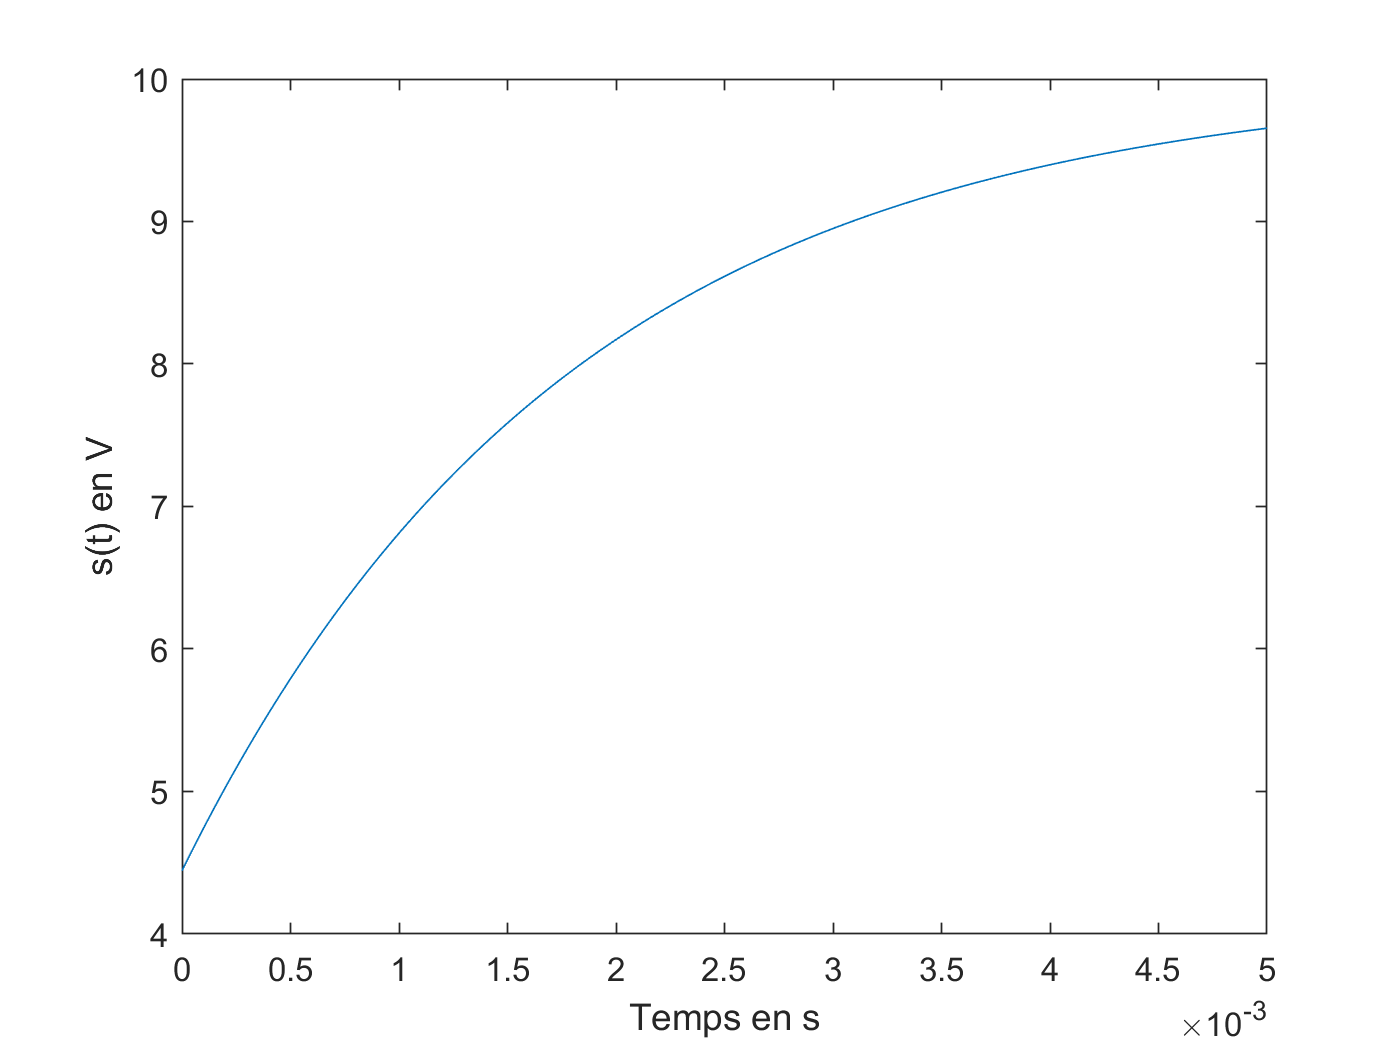


% Tracé des courbes
R1=10; R2=8; C=100e-6;E=10;
t=linspace(0,5e-3,500);
s=double(subs(s));
plot(t,s)
xlabel('Temps en s')
ylabel('s(t) en V')

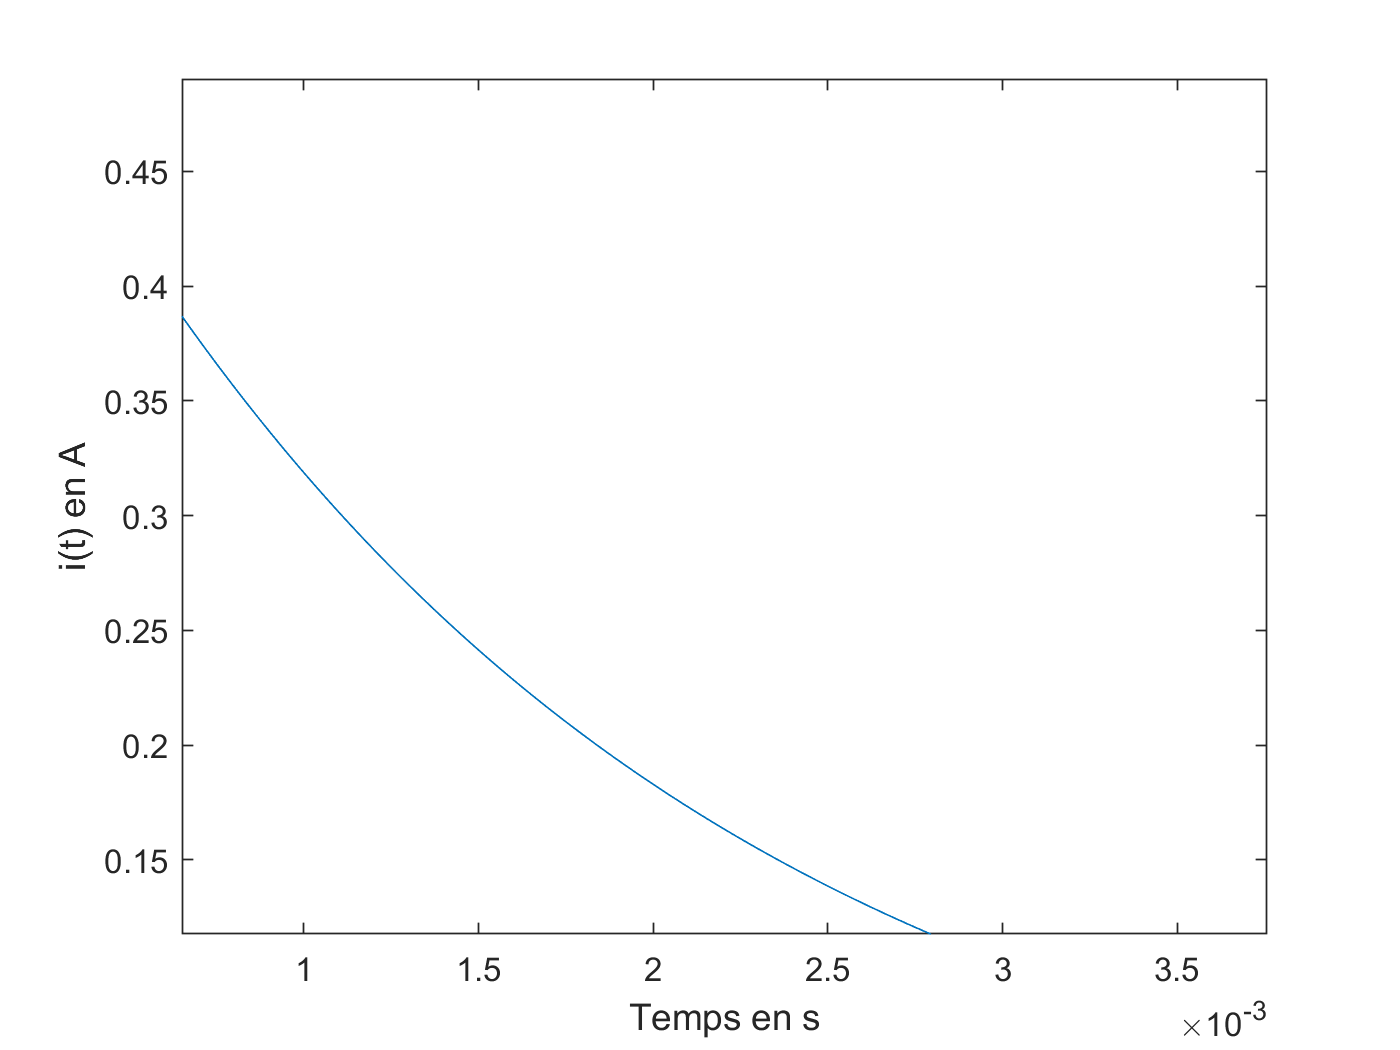

figure
i=double(subs(i));
plot(t,i)
xlabel('Temps en s')
ylabel('i(t) en A')